a) Estime por simulacao a probabilidade de nenhum alvo ter sido atingido mais do que uma vez quando n = 20 dardos e m = 100 alvos. 

E = 1e5;
n = 20;
m = 100;

mx = randi(m,n,E);
%disp(mx);
dif = zeros(1,E);

for ncol = 1:E
    col = mx(:,ncol);
    dif(ncol)=length(unique(col))==n;
end

prob = (sum(dif)/E);

disp(prob);

    0.1287



b) Estime por simulacao a probabilidade de pelo menos 1 alvo ter sido atingido 2 ou mais vezes quando n = 20 dardos e m = 100 alvos.

E = 1e5;
n = 20;
m = 100;

mx = randi(m,n,E);
dif = zeros(1,E);

for ncol = 1:E
    col = mx(:,ncol);
    dif(ncol)=length(unique(col))==n;
end

prob = 1 - (sum(dif)/E);

disp(prob);

    0.8704



c) Considere os valores de m = 1000 e m = 100000 alvos. Para cada um destes valores, faca as simulacoes necessarias para desenhar um grafico da probabilidade da alinea (b) em funcao do numero de dardos n. Considere n de 10 a 100 com incrementos de 10. Os 2 graficos devem ser sub-graficos de uma mesma figura

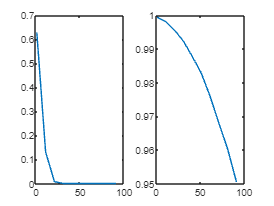

E = 1e5;
x = 1:10:100;
m1 = 100;
m2 = 100000;

y1 = zeros(1,10);
for n = 10:10:100
    mx = randi(m1,n,E);
    dif = zeros(1,E);
    for ncol=1:E
        col = mx(:,ncol);
        dif(ncol)=length(unique(col))==n;
    end
    y1(n) = sum(dif)/E;
end
%disp(y1);
y1 = y1(10:10:end);
%disp(y1);

y2 = zeros(1,10);
for n = 10:10:100
    mx = randi(m2,n,E);
    dif = zeros(1,E);
    for ncol=1:E
        col = mx(:,ncol);
        dif(ncol)=length(unique(col))==n;
    end
    y2(n) = sum(dif)/E;
end

%disp(y1);
y2 = y2(10:10:end);
%disp(y1);

subplot(1,2,1);
plot(x,y1);

subplot(1,2,2);
plot(x,y2);

d) Considere o valor de n = 100 dardos. Faca as simulacoes necessarias para desenhar um grafico da probabilidade da alinea (b) em funcao dos valores de m = 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000 alvos.

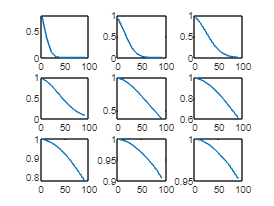

E = 1e5;

x = 1:10:100;
m = [200,500,1000,2000,5000,10000,20000,50000,100000];

i=1;
%y=zeros(10,10);
for m1 = m
    y1=zeros(1,10);
    for n = 10:10:100
        mx = randi(m1,n,E);
        dif = zeros(1,E);
        for ncol = 1:E
            col = mx(:,ncol);
            dif(ncol)=length(unique(col))==n;
        end
        y1(n) = sum(dif)/E;
    end
    %disp(y1);
    % order array
    y1 = y1(10:10:end);
    %disp(y1);
    subplot(3,3,i);
    plot(x,y1);
    i=i+1;
end